data = zeros(1,360);
interval = 45;
data = simulated_ideal_response_curve(interval).data

data =    63.7800  101.5602  121.4663  107.5606   81.2591   68.1048   63.6658   53.1036


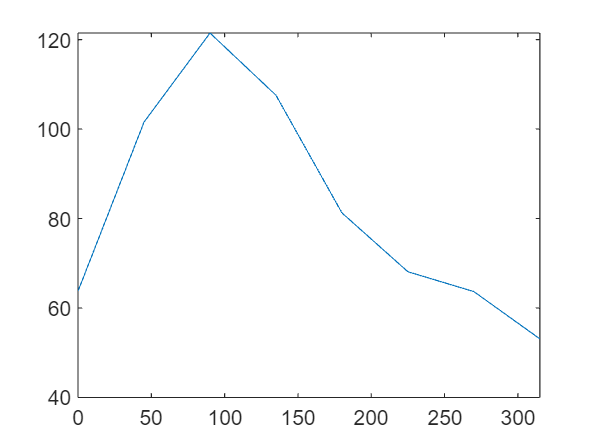

ang = 0:interval:359;
plot(ang,data)

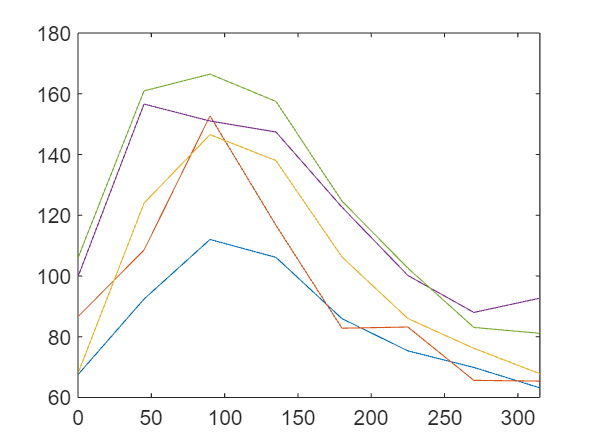

data = repmat(data,5,1) + 7*randn(5,360/interval);
plot(ang,data(1,:),ang,data(2,:)+10,ang,data(3,:)+20,ang,data(4,:)+30,ang,data(5,:)+40),

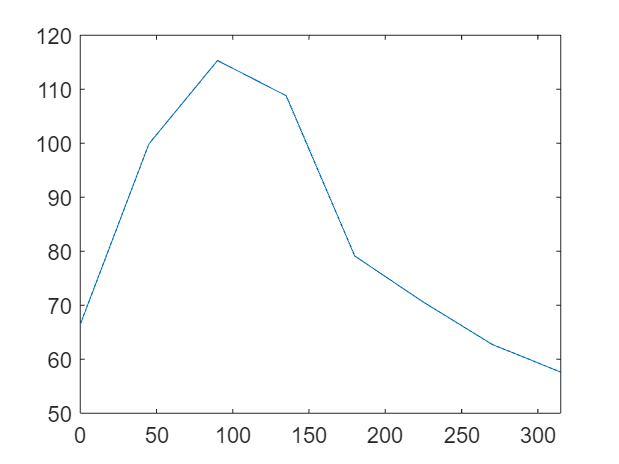

data1 = mean(data,1);
plot(ang,data1),

tic;
lik = bayes_grid_function(data,interval).lik;
lik = lik/sum(lik,'all');
toc;

plot_bayes_oridir(lik)